# Topic 1

I chose $f\left(x\right)=x^4 +\sin \left(x\right)$, and $a=1$

clearvars
clf
% gen data
syms f(x)
f(x)=@(x)(x^4+sin(x))

$$f(x) = \sin\left(x\right)+x^{4}$$

df(x) = diff(f(x))

$$df(x) = \cos\left(x\right)+4\,x^{3}$$

ddf(x) = diff(df(x))

$$ddf(x) = 12\,x^{2}-\sin\left(x\right)$$

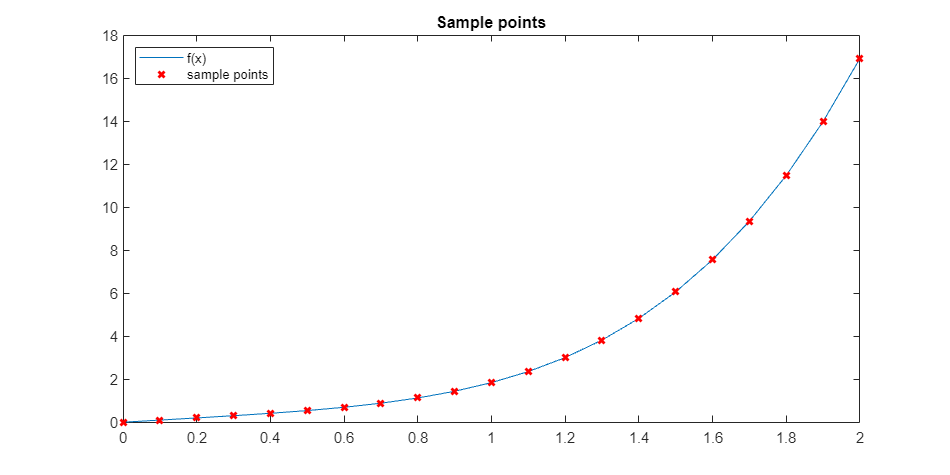

x = 0:.1:2; % h=0.1; x(11)=1=a

%plot data
figure
set(gcf,'Position',[100 100 1200 600])
plot(x, f(x))
hold on
plot(x, f(x), 'rx', 'LineWidth', 2)
title('Sample points')
legend(["f(x)", "sample points"], 'Location','northwest')
hold off

## Task 1

% forward 
dfdx_f = (-3*f(x(11))+4*f(x(12))-f(x(13)))/(2*0.1);
fprintf("Forward: %f", vpa(dfdx_f))

Forward: 4.455887

% backward
dfdx_b = (3*f(x(11))-4*f(x(10))+f(x(9)))/(2*0.1);
fprintf("Backward: %f", vpa(dfdx_b))

Backward: 4.468307

% central
dfdx_c = (f(x(12))-f(x(10)))/(2*0.1);
fprintf("Central: %f", vpa(dfdx_c))

Central: 4.579402

% real dfdx
fprintf("Real: %f", vpa(df(x(11))))

Real: 4.540302

## Task 2

% forward 
ddfdx_f = (2*f(x(11))-5*f(x(12))+4*f(x(13))-f(x(14)))/0.1^2;
fprintf("Forward: %f", vpa(ddfdx_f))

Forward: 10.930333

% backward
ddfdx_b = (2*f(x(11))-5*f(x(10))+4*f(x(9))-f(x(8)))/0.1^2;
fprintf("Backward: %f", vpa(ddfdx_b))

Backward: 10.931410

% central
ddfdx_c = (f(x(12))-2*f(x(11))+f(x(10)))/0.1^2;
fprintf("Central: %f", vpa(ddfdx_c))

Central: 11.179230

% real ddfdx
fprintf("Real: %f", vpa(ddf(x(11))))

Real: 11.158529

## Task 3

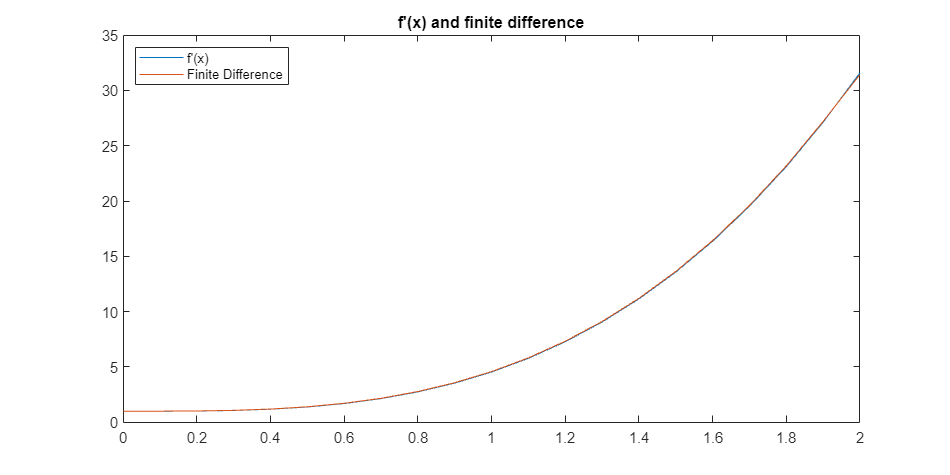

n=length(x);

%cal dfdx
dfdx = zeros(n, 1);
dfdx(1) = (-3*f(x(1))+4*f(x(2))-f(x(3)))/(2*0.1); % forward diff at left point
for i=2:n-1
    dfdx(i)=(f(x(i+1))-f(x(i-1)))/(2*0.1); % central diff at interior points
end
dfdx(n) = (3*f(x(n))-4*f(x(n-1))+f(x(n-2)))/(2*0.1); % backward diff at right point

%plot f'(x)
plot(x, df(x))
hold on
plot(x, dfdx)
title("f'(x) and finite difference")
legend(["f'(x)", "Finite Difference"], 'Location','northwest')
hold off

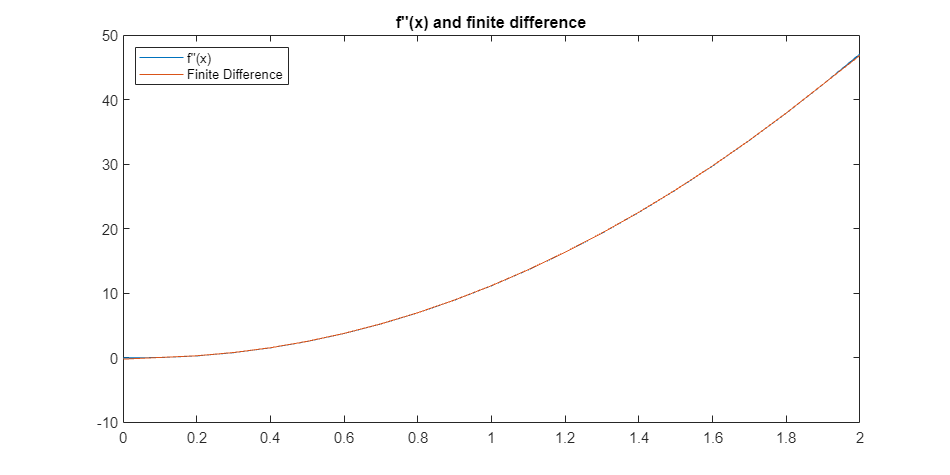


%cal ddfdx
ddfdx = zeros(n,1);
ddfdx(1) = (2*f(x(1))-5*f(x(2))+4*f(x(3))-f(x(4)))/0.1^2;
for i=2:n-1
    ddfdx(i)=(f(x(i+1))-2*f(x(i))+f(x(i-1)))/0.1^2;
end
ddfdx(n) = (2*f(x(n))-5*f(x(n-1))+4*f(x(n-2))-f(x(n-3)))/0.1^2;

%plot f''(x)
plot(x, ddf(x))
hold on
plot(x, ddfdx)
title("f''(x) and finite difference")
legend(["f''(x)", "Finite Difference"], 'Location','northwest')
hold off

## Function define